clear all
close all
clc

run("BASIC.m")
C=poly([0.6 0.7]);

Question_mark='Q14-MV adaptive';
[uc,t,Status,tfinal,Noise]=Datagen_Stochastic(2,0.1,500,0.01,C);

Status = '-Cololerd NOISE-'

Titlework=[Question_mark,Status]

Titlework = 'Q14-MV adaptive-Cololerd NOISE-'


N = numel(t) ;

Parameters_in_den=2;
Parameters_in_num=2;
Parameters_in_Nio=3;
Nv_sys=Parameters_in_den+Parameters_in_num+Parameters_in_Nio;

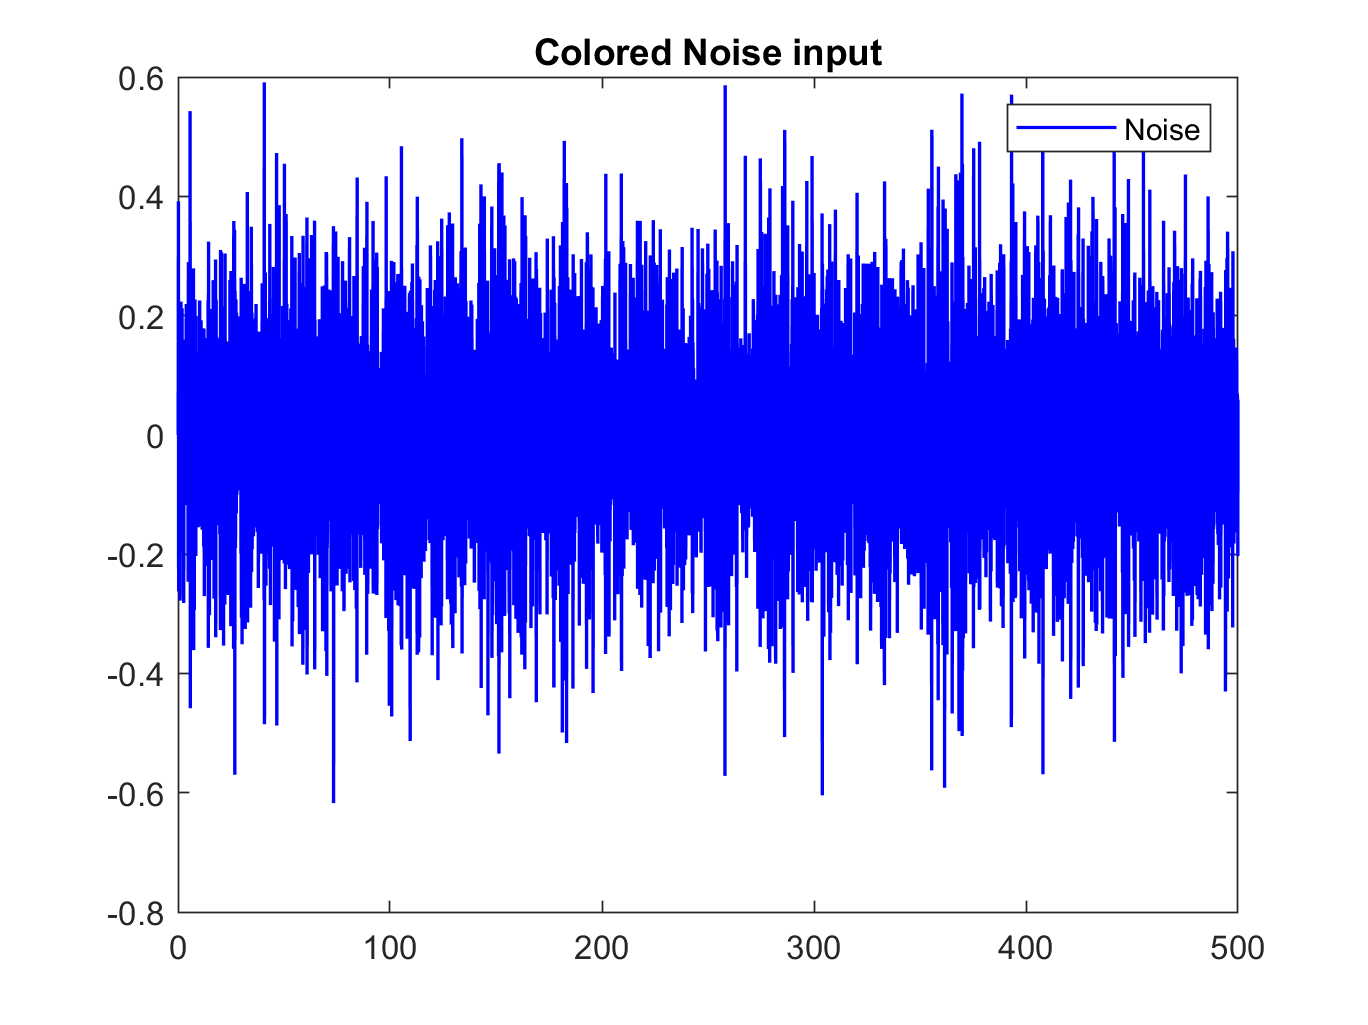

plot(t,Noise,'b','LineWidth',1)
title('Colored Noise input')
legend('Noise')
print(gcf,[Titlework , num2str(plot_counter) ' Colored Noise input.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

Ac=conv(C,B);
d0=1;
D0=zeros(d0,1);
D0(1)=1;
if D0==[]
    Ac=conv(C,B);
else
    Ac=conv(Ac,D0);

end

y=zeros(1,numel(t));
y(1,1:10)=0.*ones(1,10);%initial condotion
u=zeros(1,numel(t));
u(1,1:10)=0.0*ones(1,10);%initial condotion

theta_hat=zeros((Nv_sys),numel(t));
theta_hat(:,3)=ones(1,7);%initial condotion
p=10^6*eye(Nv_sys);%initial condotion

var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);

for i=4:numel(t)
    y(i)=-A(2:end)*[y(i-1:-1:i-2)]'+B*[u(i-1:-1:i-2)]'+ [Noise(i)]';
    fi_small=[-y(i-1);-y(i-2);u(i-1);u(i-2);Noise(i-1:-1:i-3)];
    eps(i)=y(i)-fi_small'*theta_hat(:,i-1);
    p=((p)^(-1)+fi_small*transpose(fi_small))^(-1);
    theta_hat(:,i)=theta_hat(:,i-1)+p*fi_small*eps(i);

    [R , S ] = Diophantine([1 theta_hat(1:2,i)'] , theta_hat(3:4,i)' , Ac);

    y(i)= -A(2:3)*[y(i-1:-1:i-2)]'+ B*[uc(i-1:-1:i-2)]+Noise(i);
    u(i)=(-R(2)*u(i-1)-S*[y(i:-1:i-1)]')./R(1);
    if abs(u(i))>1
        u(i)=sign(u(i))*1;
    end
    var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
    var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;
end

## ELS convergence

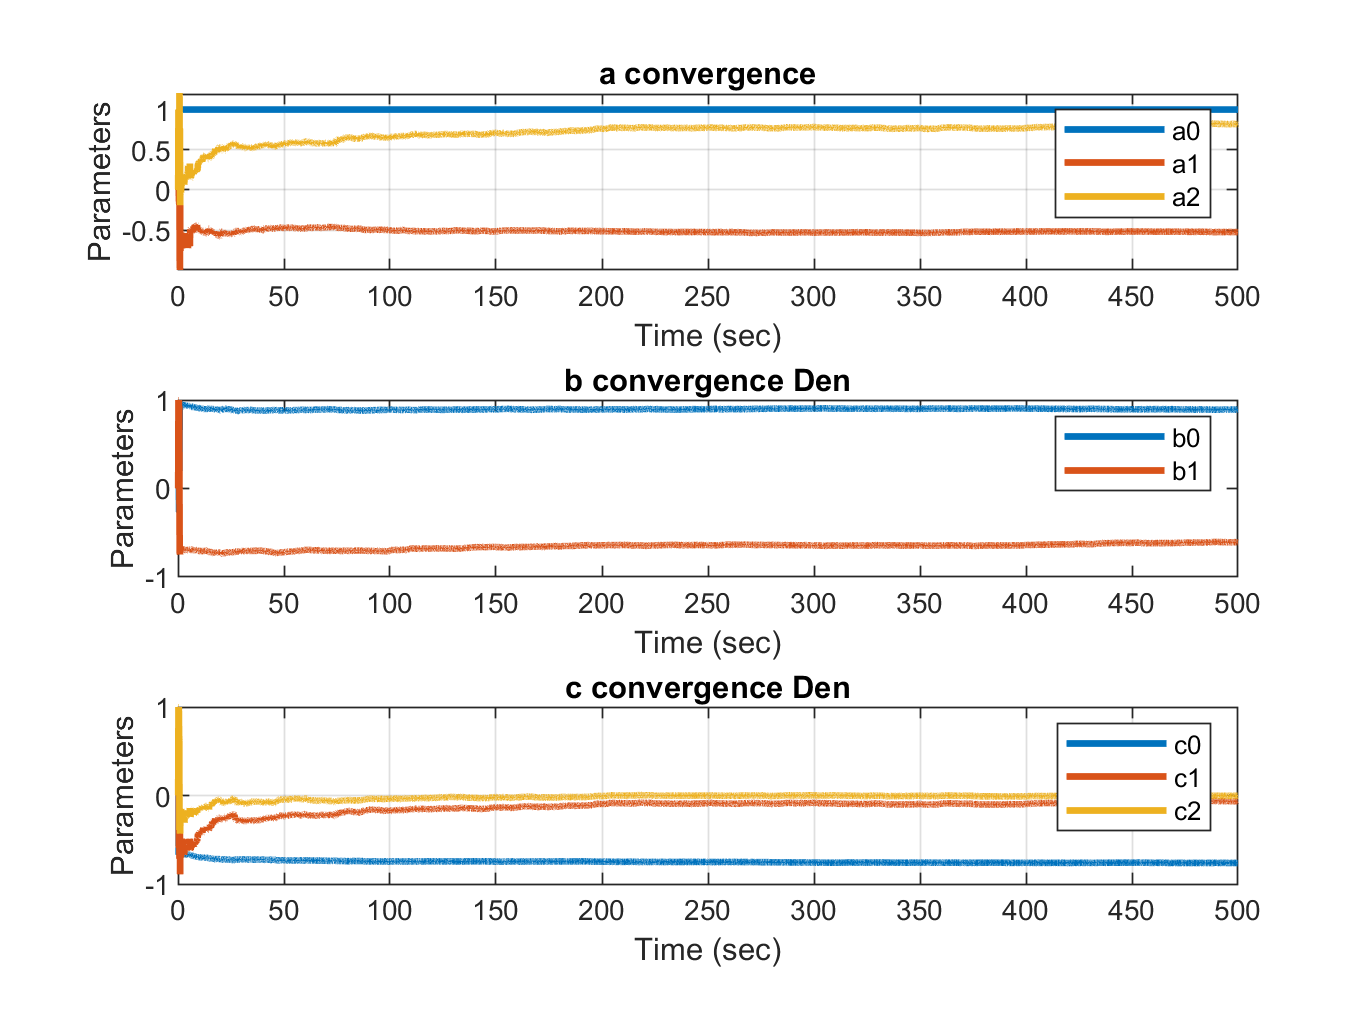

ELS_Convergence(3,[ones(1,numel(t)) ; theta_hat(1:2,:)],'a',2,theta_hat(3:4,:),'b',3,theta_hat(5:7,:),'c',t,Titlework,1,plot_counter)

        plot_counter=plot_counter+1;

## Output and control signal plotting

General Input v.s. Output

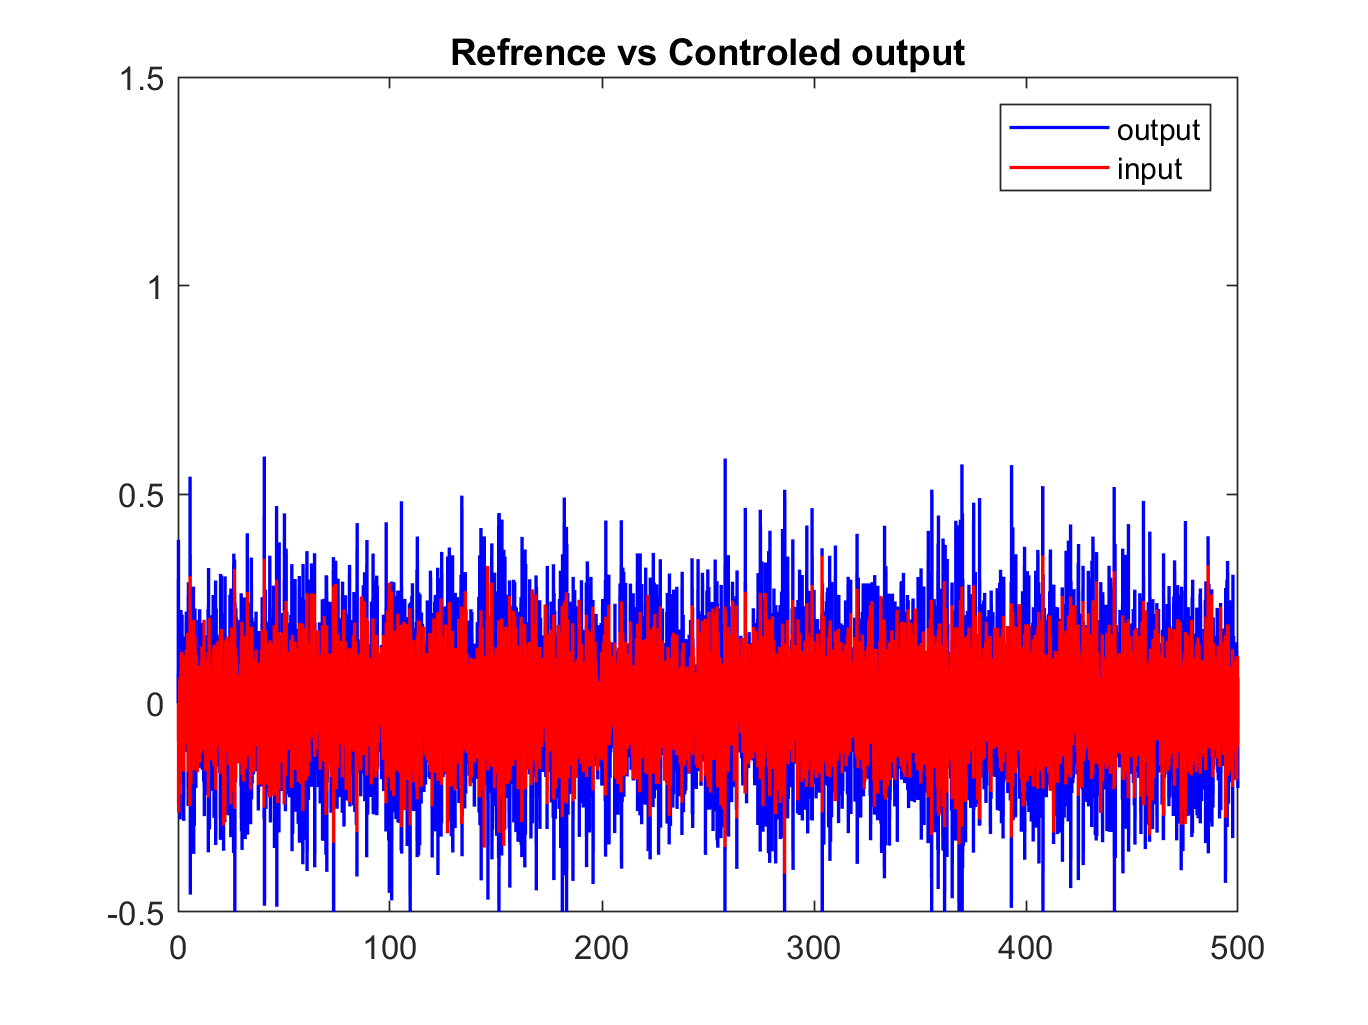

figure()
plot(t,Noise,'b-',t,y,'r-','LineWidth',1)
title('Refrence vs Controled output')
legend('output','input')
xlim('auto')
ylim([-0.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Noise vs Controled output.png'],'-dpng','-r400');

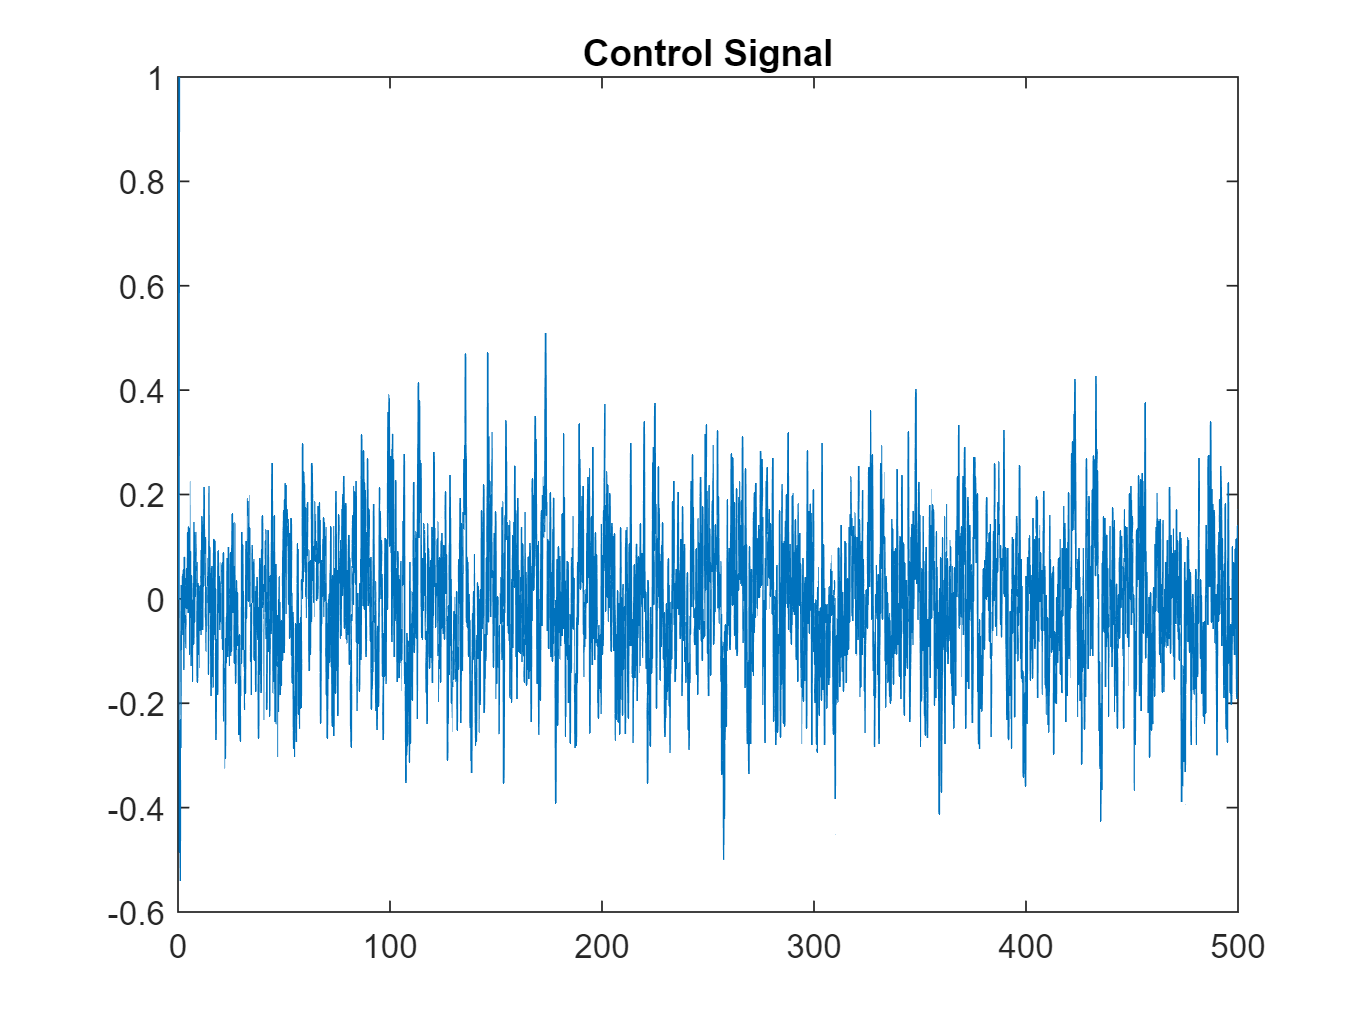

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
% xlim('auto')
% ylim([-1.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Variance plotting

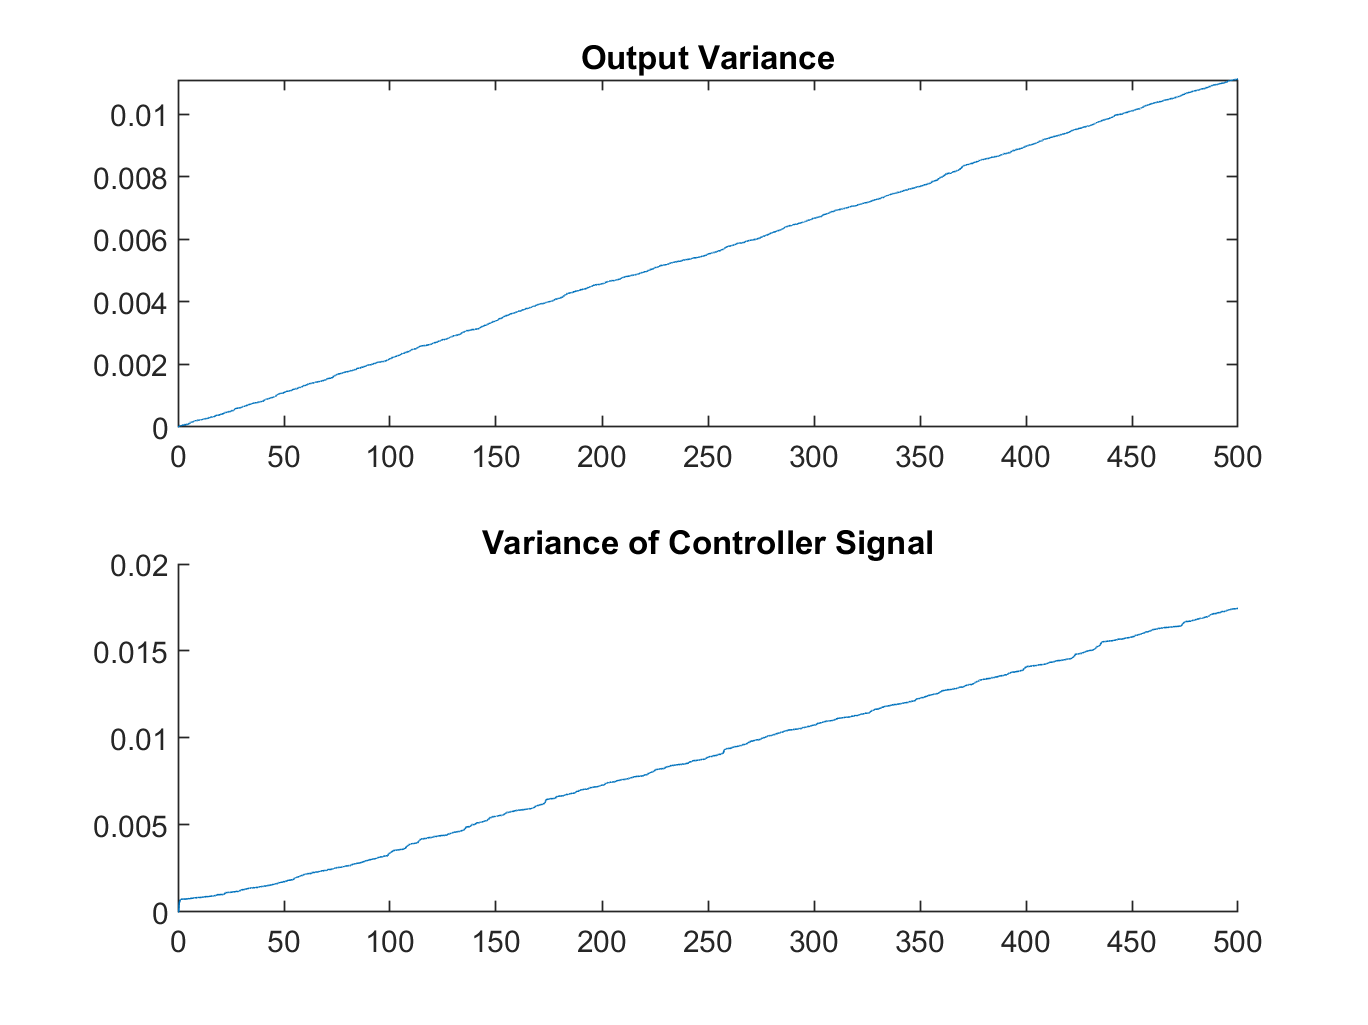

figure
subplot(211)
plot(t,var_y)
hold on
title('Output Variance')

subplot(212)
hold on
title('Variance of Controller Signal')
plot(t,var_u)
print(gcf,[Titlework , num2str(plot_counter) ' Variance.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Mean plotting

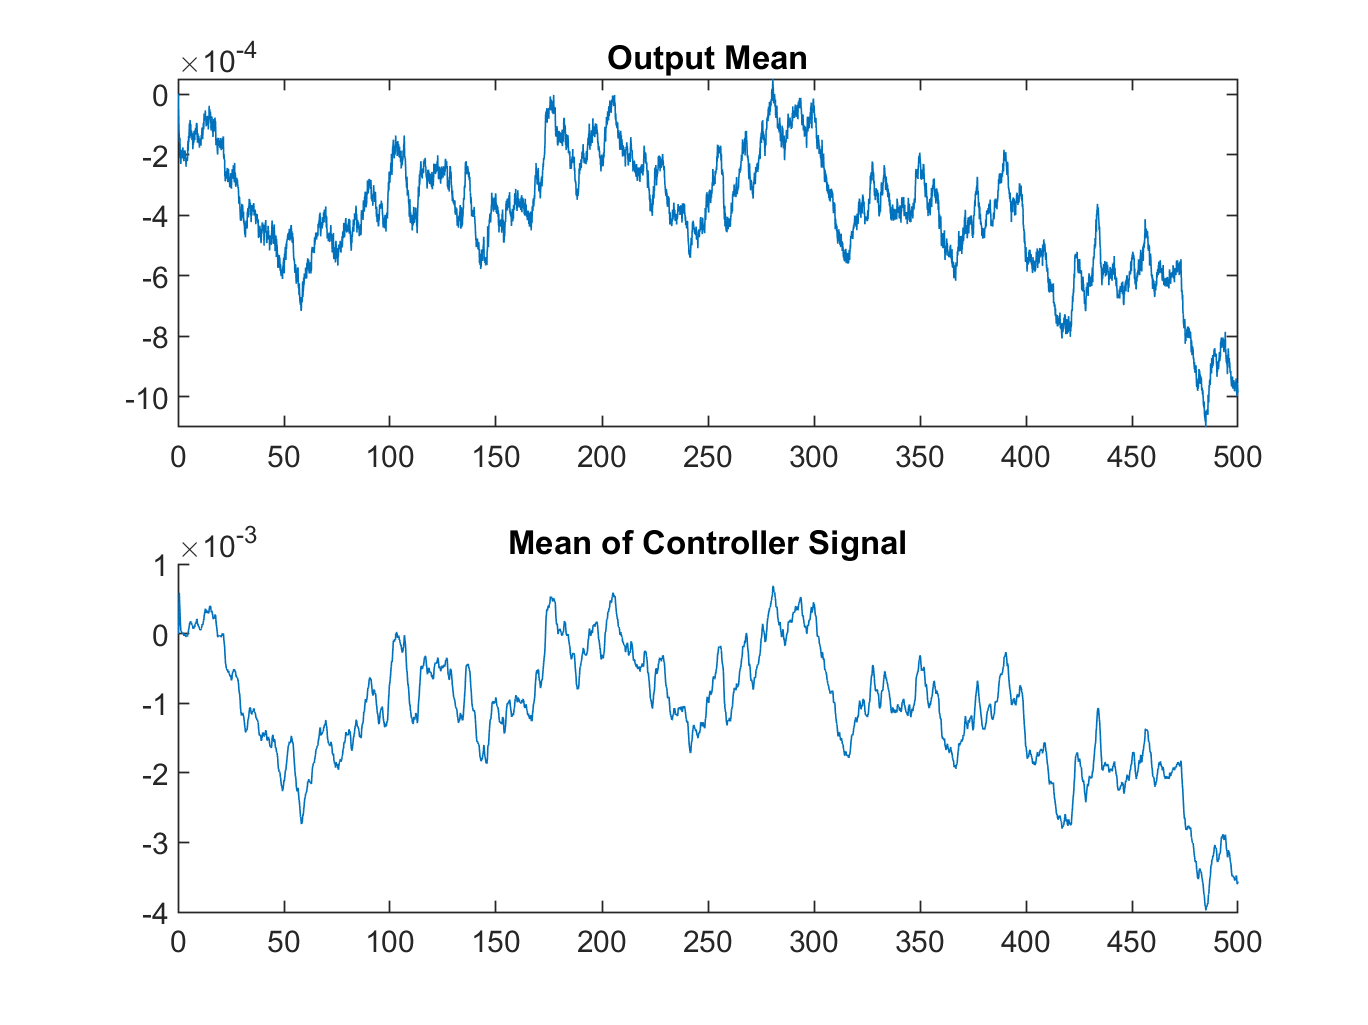

figure
subplot(211)
plot(t,mean_y)
hold on
title('Output Mean')

subplot(212)
hold on
plot(t,mean_u)
title('Mean of Controller Signal')
print(gcf,[Titlework , num2str(plot_counter) ' mean.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Accumulated loss plotting

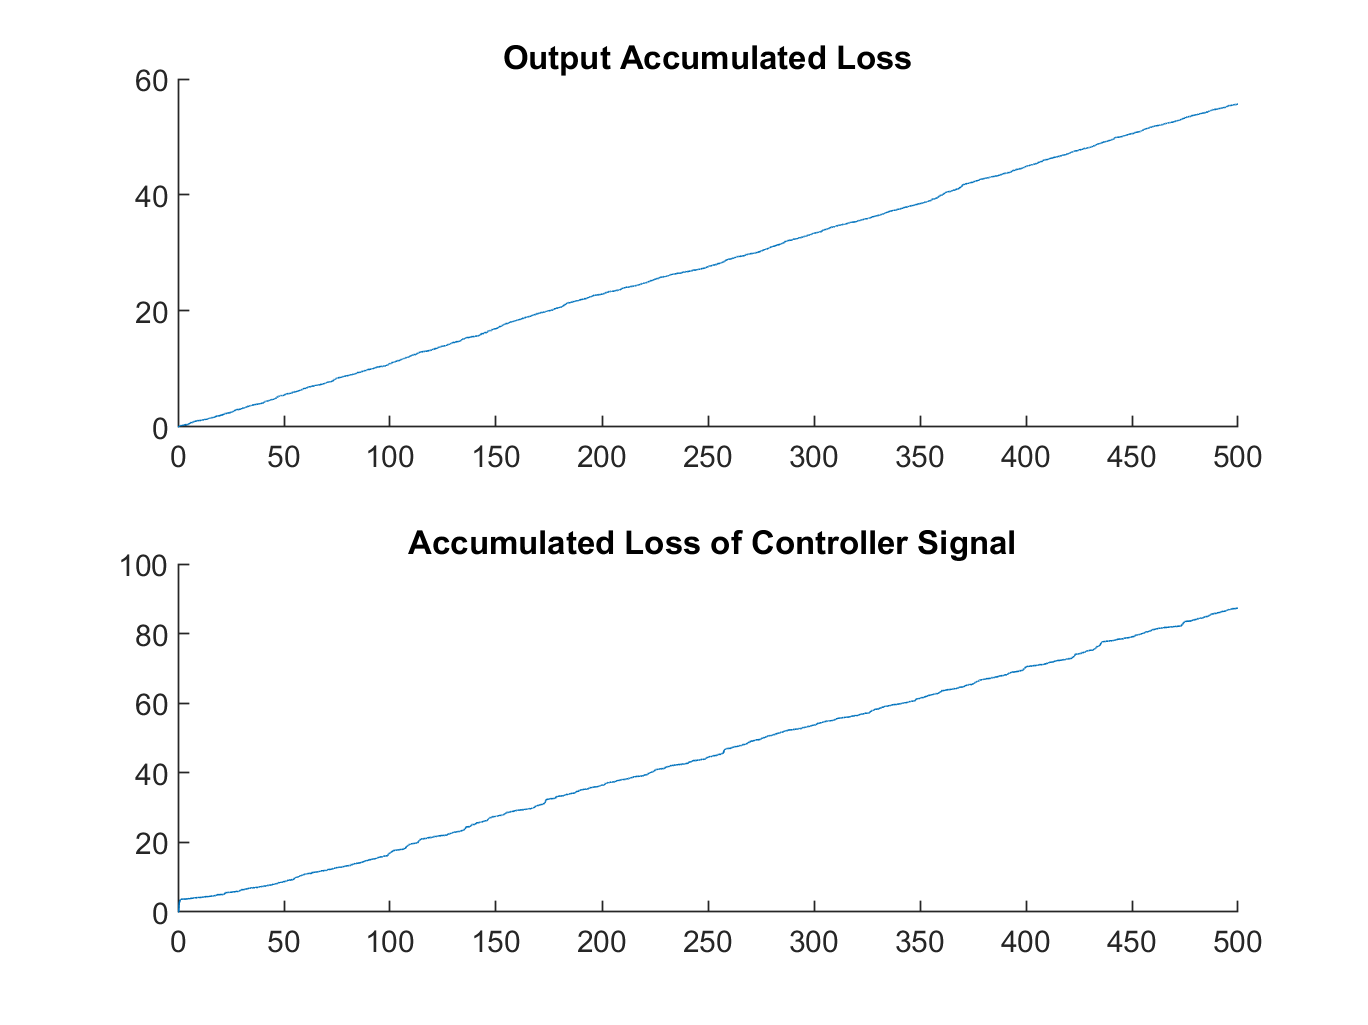

figure
subplot(211)
hold on
plot(t,ACLS_y)
title('Output Accumulated Loss')

subplot(212)
hold on
title(' Accumulated Loss of Controller Signal')
plot(t,ACLS_u)
print(gcf,[Titlework , num2str(plot_counter) ' Accumulated Loss.png'],'-dpng','-r400');

plot_counter=plot_counter+1;